x0 = [2;1];
a = 100;

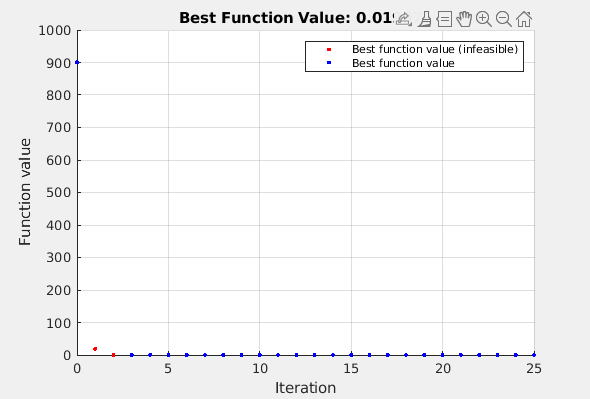


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


% Pass fixed parameters to objfun
objfun = @(x)objectiveFcn(x,a);

% Set nondefault solver options
options = optimoptions("fmincon","PlotFcn","optimplotfvalconstr");

% Solve
[solution,objectiveValue] = fmincon(objfun,x0,[],[],[],[],[],[],...
    @constraintFcn,options);


% Clear variables
clearvars objfun options

solution

solution =     1.1413
    1.3029


objectiveValue

objectiveValue = 0.0200

View the nonlinear constraint function values at the solution.

[ccons,ceqcons] = constraintFcn(solution)

ccons =    -2.0000   -0.0000



ceqcons =

     []



function f = objectiveFcn(x,a)
f = a*(x(2) - x(1)^2)^2 + (1 - x(1))^2;
end

function [c,ceq] = constraintFcn(x)
c(1) = x(1)^2 + x(2)^2 - 5;
c(2) = 3 - x(1)^2 - x(2)^2;
ceq = [];  % No equality constraints
end